%パラメータ設定
numNode = 10; %ノード数
completeGraph = complete_graph(numNode); %N_node個のノードを持つ完全グラフ
adjacencyMatrix = adjacency(completeGraph); %completeGraphの隣接行列
omega = 3; %固有振動数
dencityBetweenNodes = 8; %ノード間の結合密度
p = 0:0.1:1; %不活性ノードの割合
activeNode = 1; %活性ノードの自己振幅係数
inactiveNode = -1; %不活性ノードの自己振幅係数
t_max = 600;
dt = 0.05;
t_steps = t_max / dt;
t = linspace(0, t_max, t_steps);
ntrans = 6000; %過渡期
t_span = [0 t_max];
pred_time = 3000;
train_param = [0.1 0.2 0.3];
z_abs_data = nan(1, length(p)); %zの平均振幅を格納するNaN配列
z_initial = ones(numNode, 1) + 1i * ones(numNode, 1); %初期値 1 + 0*i
z_initial = [real(z_initial); imag(z_initial)]';
dim = numNode*2; %ノード数の実部と虚部
%----------------------------------------------------------------------------------------------------% 初期条件
z_data = solve_model(t_steps, ntrans, dim, t, train_param, numNode, ...
    activeNode, inactiveNode, z_initial, omega, dencityBetweenNodes, adjacencyMatrix)';
size(z_data)

ans =           60        6000


disp('original dynamics generated');

original dynamics generated


%--------------------------------------------------------------------------------------------------


% ESNのパラメータ設定
Nt = 4500;  % training length
Np = 400;    % predicting length
wa = 100;    % warmup length
transit = 50; % abandon reservoir length

% ハイパーパラメータの取得
beta = 1e-5 + (1e-2 - 1e-5) * rand;
W_in_a = 3 + (0.1 - 3) * rand;
alpha = 1 + (0 - 1) * rand;
eig_rho = 1 + (0 - 1) * rand;
n = randi([100, 1000]);
k = randi([1, 20]);
kb = 1 + (0 - 1) * rand;
pb = 1 + (0 - 1) * rand;

%ハイパーパラメータンの値の表示
fprintf('beta = %f\n', beta);

beta = 0.006642


fprintf('W_in_a = %f\n', W_in_a);

W_in_a = 2.700007


fprintf('alpha = %f\n', alpha);

alpha = 0.053320


fprintf('eig_rho = %f\n', eig_rho);

eig_rho = 0.038804


fprintf('n = %d\n', n);

n = 714


fprintf('k = %d\n', k);

k = 20


fprintf('kb = %f\n', kb);

kb = 0.018982


fprintf('pb = %f\n', pb);

pb = 0.065803



ESN_par = [n, alpha, beta, Nt, Np, transit, dim];
W_input = W_inn(n, dim, W_in_a);
W_reservoir = W_ress(k, n, eig_rho);
disp('ESN built');

ESN built



disp('Training started');

Training started


W_out = create_ESN(ESN_par, z_data, train_param, W_input, W_reservoir, kb, pb);
disp('Training done');

Training done


     0



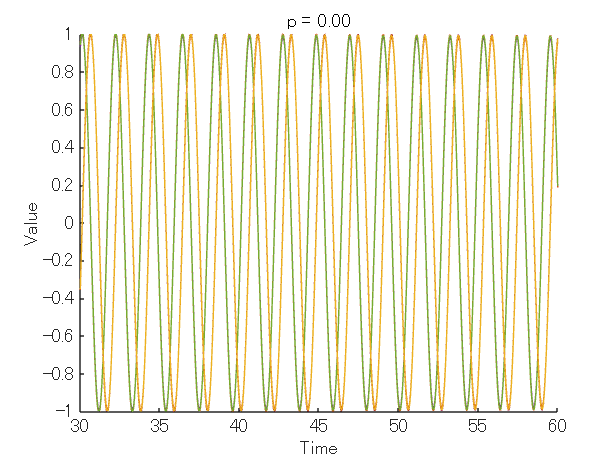

    0.1000



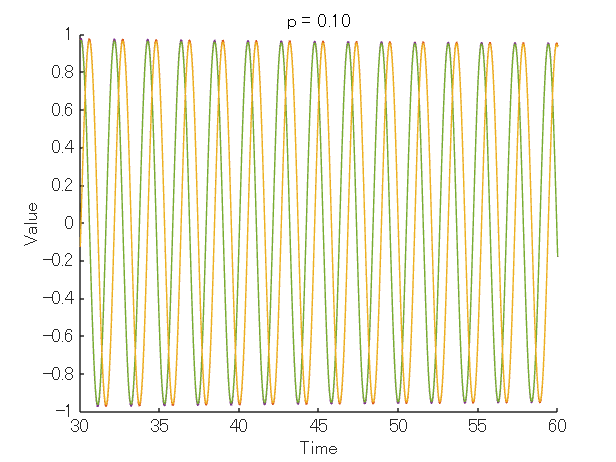

    0.2000



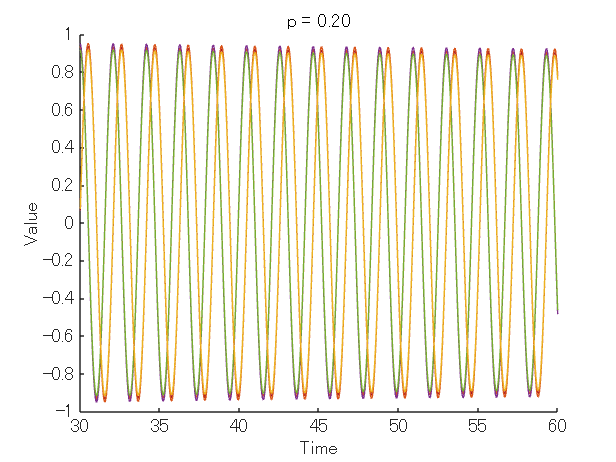

    0.3000



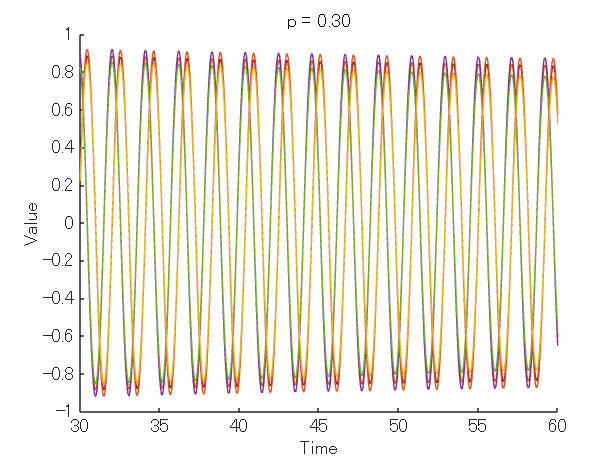

    0.4000



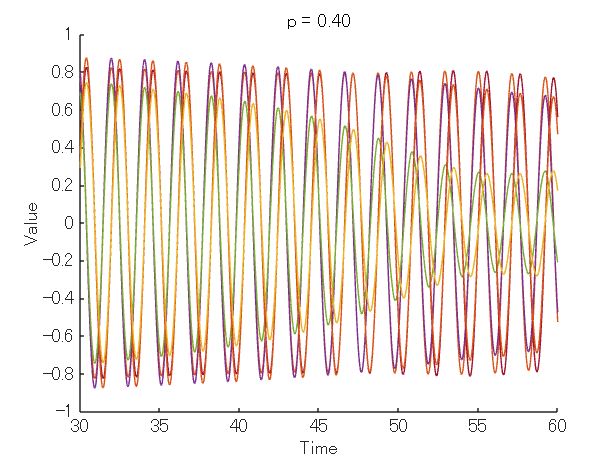

    0.5000



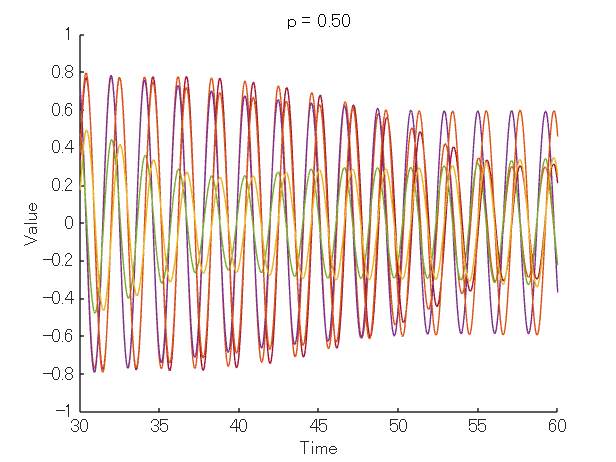

    0.6000



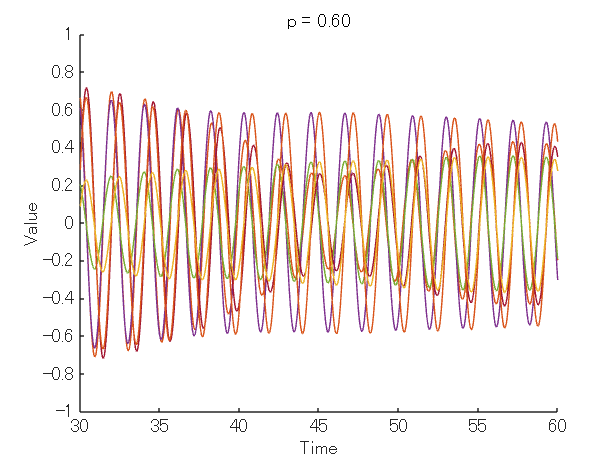

    0.7000



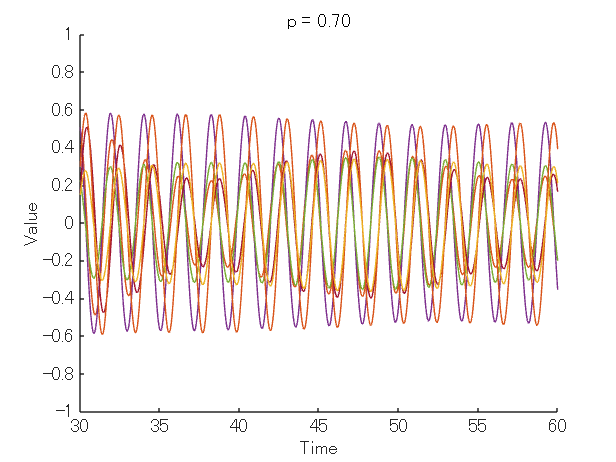

    0.8000



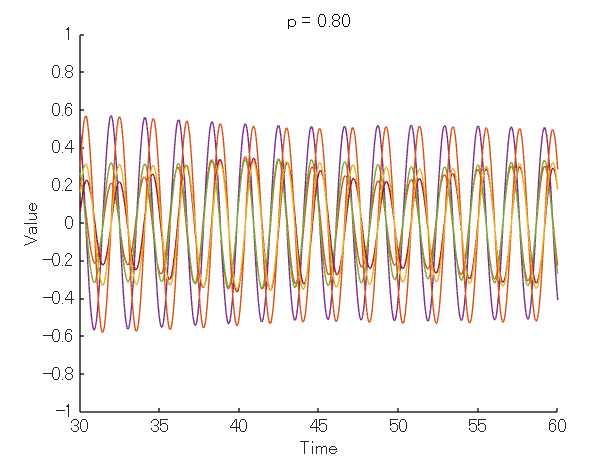

    0.9000



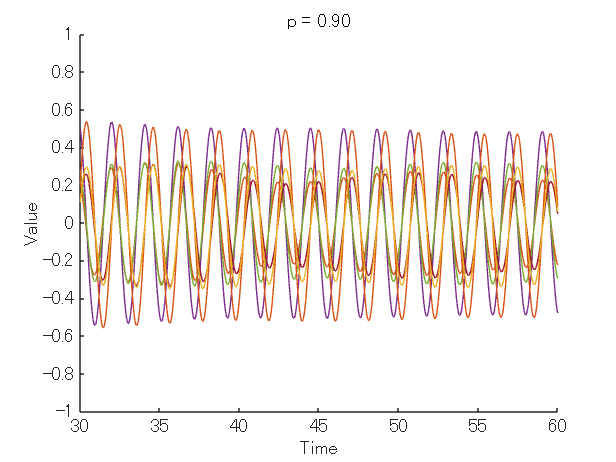

     1



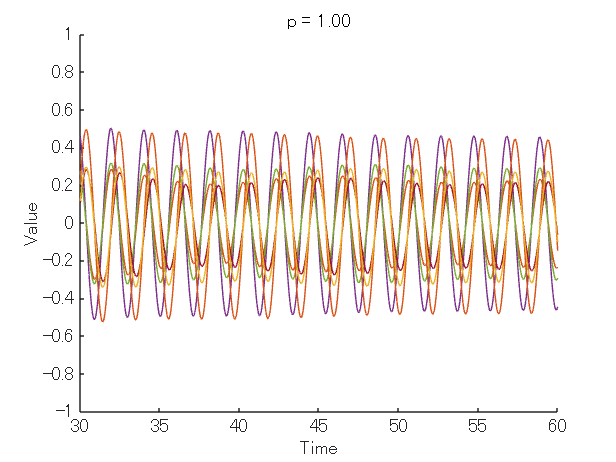


%--------prediction for a new parameter--------------------------------------------------------------------
par = 0:0.1:1; % new parameter
time = 0:0.05:(pred_time-1001)*dt;
for ind_par = 1:length(par)
   disp(par(ind_par));
   pred_data = prediction(pred_time, alpha, n, par(ind_par), z_initial, W_out, W_reservoir, W_input, kb, pb, numNode);
   odd_rows = pred_data(1:2:end, :);
    
   % プロット
   figure;
   hold on;
   for i = 1:size(odd_rows, 1)
       plot(time, odd_rows(i, :)); % 各奇数行をプロット
   end
   hold off;

   % グラフの装飾
   p_str = sprintf('%.2f', par(ind_par)); 
   title(sprintf('p = %s', p_str),'FontSize', 16);
   xlabel('Time', 'FontSize', 14);
   xlim([30 60])
   ylabel('Value', 'FontSize', 14);
   ylim([-1 1]);
   set(gca, 'FontSize', 12);
end